# Inverted Pendulum

clearvars; clc; close all
%set(groot,'defaultFigurePosition',[0 0 900 900])

## Data

L = 0.3; % pendulum length (m)
M = 0.5; % mass of cart (kg)
m = 0.2; % mass of pendulum (kg)
b = 0.1; % friction coefficient for cart
max_F = 10; % max allowed force (N)
rail_length = 1;  % length of the rail
cart_length = 0.2; % length of the cart
I = 0.006; % traagheidsmoment
g = 9.81; % valversnelling

## Matrices opstellen

N = I*(M+m) + M*m*L^2;
A = [0 1 0 0;
    0 -(I+m*L^2)*b/N m^2*g*L^2/N 0;
    0 0 0 1;
    0 -m*L*b/N m*g*L*(M+m)/N 0];
B = [0;
    (I+m*L^2)/N;
    0;
    m*L/N];
C = [1 0 0 0;
    0 0 1 0];
D = [0;
    0];
states = {'x' 'v' 'theta' 'w'};
inputs = {'u'};
outputs = {'x'; 'theta'};
S = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);
% Kleine coeff nog naar 0 zetten


## Controleerbaarheid

rank(ctrb(A,B)) == 4

ans = logical
   1


## Observeerbaarheid

rank(obsv(A,C)) == 4

ans = logical
   1


## Open Lus

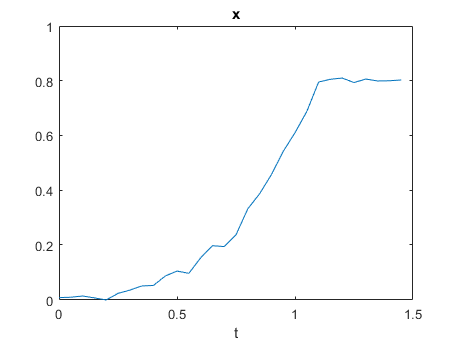

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 60);

% Define parameters and modes
T_sample = 0.05;
n_samples = 30;
ts = (0:n_samples-1)*T_sample;

% Standard modes (must correspond to similar mode in Arduino code)
OPEN_LOOP   = 0;
CLASSICAL   = 1; %classical (PID family) controller
STATE_SPACE = 2;
EXTENDED    = 3;

mode = OPEN_LOOP;
w = 1.0;
set_mode_params(arduino, mode, w, [])
reset_system(arduino)
Y = get_response(arduino, w, n_samples);

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
figure; plot(ts, x); title("x"); xlabel('t')

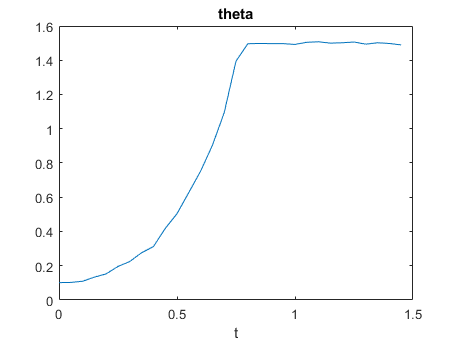

figure; plot(ts, theta); title("theta"); xlabel('t')

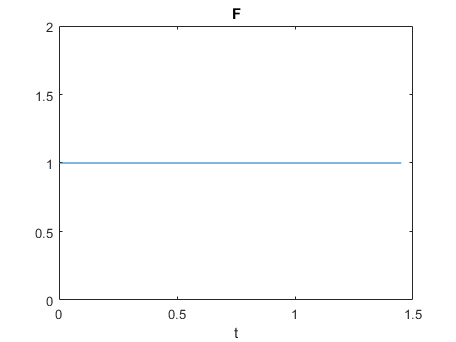

figure; plot(ts, u); title("F"); xlabel('t')


close_connection(arduino)
clear arduino

## Classical Controller

Hoek

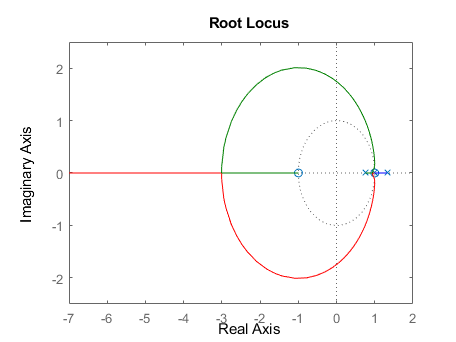

Ts = 0.05; % Sample time
Sd = c2d(S,Ts); % Discretiseren
Sdtf = tf(Sd); % We nemen de transferfunctie zodat we verder kunnen werken
% met enkel de transferfunctie van theta => SISO

% Zonder regelaar
rlocus(Sd(2))

ps2 = pole(Sdtf(2)) % Het berekenen van de polen voor theta

ps2 =     1.3210
    0.9929
    0.7555


zs2 = zero(Sdtf(2)) % Het berekenen van de nulpunten voor theta

zs2 =     1.0000
   -0.9970


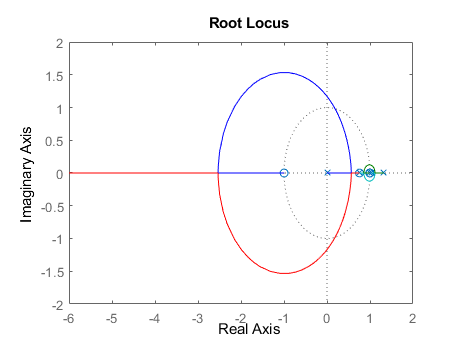


% Regelaar
Rd2 = zpk([ps2(2:end)],[0,1.04],48.1,Ts); % Implementatie van een eerste PID
% Nulpunten:
%   Nulpunten leggen op de polen binnen de eenheidscirkel zodat ze niet meer
%   zullen bewegen voor een variabele gain. Op de buitenste wordt er geen
%   nulpunt gelegd zodat het systeem kan gestabiliseerd worden.
% 
% Polen:
%   Er wordt een pool in 1.04 (arbitrair, maar wel nog steeds tussen de rechts uiterste pool
%   en het rechtse uiterste nulpunt) geplaatst. Die pool zal ervoor zorgen
%   dat de rootlocus wijzigt. Door de nieuwe vorm van de rootlocus is het
%   mogelijk adhv de gain de polen binnen de eenheidscirkel te plaatsen.
%   Door het criterium X hebben we een extra pool nodig. We plaatsen de
%   pool in 0 zodat we een snelle pool hebben. Het voordeel van de snelle
%   pool.
% 
% Gain:
%   We wensen de polen binnen de eenheidscirkel te plaatsen en kiezen
%   ervoor om deze eveneens op de reële as te laten vallen teneinde geen
%   imaginair component te verkrijgen. Daardoor wordt het oscillair gedrag
%   vermeden. Om de waarde van de gain te bepalen werd de rootlocus geplot
%   en de gain bepaald op de positie waar de twee rechtse krommes elkaar
%   binnen de eenheidscirkel raken. We vinden dat een gain van 48.1
%   vereist is en steken deze onmiddelijk in de definitie van Rd2.
rlocus(Rd2*Sd(2))

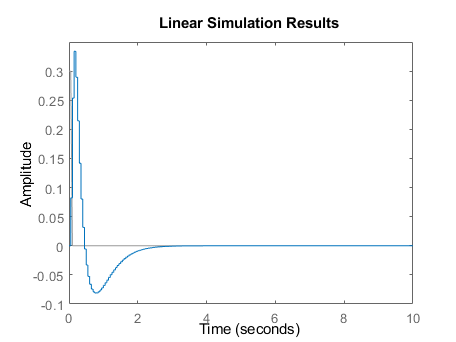

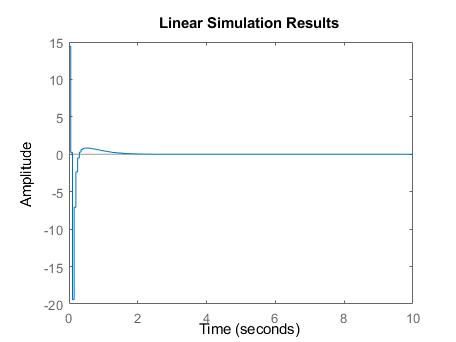

SdCl_1stLoop =
 
  From input "u" to output...
        0.10914 (z+0.997) (z-0.7807) (z-1.281)
   x:  ----------------------------------------
       (z-1) (z-0.3718) (z^2 - 1.715z + 0.7354)
 
                0.27425 (z+0.997) (z-1)
   theta:  ----------------------------------
           (z-0.3718) (z^2 - 1.715z + 0.7354)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



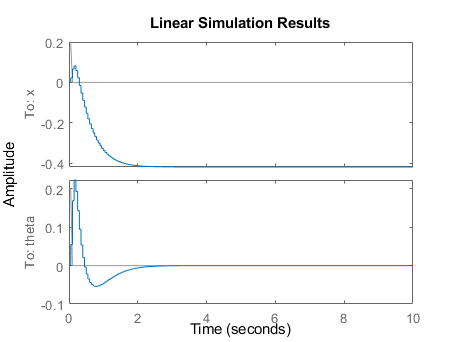


% We zullen geen zero-static-error controller implementeren voor de hoek.
% Dit zou overeenkomen met het plaatsen van een pool in 1.
% Een zero-static-error controller is gewenst indien er een stap aangelegd
% wordt. Dit zullen we nooit doen voor de hoek, wegens de fysische limieten
% voor de positie van het karretje. Het ontwerp van een zero-static-error
% controller voor de controle van de positie van het karretje is
% daarentegen wel een optie, gezien we hier wel een stap aan zullen leggen.

t = 0:Ts:10;
% Er worden geen impulsen of stappen aangelegd aangezien de hoek in
% realiteit niet zo'n verloop heeft. Daarom wordt gebruikgemaakt van lsim.
lsim(feedback(Rd2*Sdtf(2),1),[0.3 0.3 zeros(1,length(t)-2)],t) % Output y
lsim(feedback(Rd2,Sdtf(2)),[0.3 0.3 zeros(1,length(t)-2)],t) % Kracht F

SdCl_hoek_Loop = minreal(feedback(Rd2*Sdtf,[0 1]))
% Minreal vereenvoudigt de uitdrukking om het overzicht te bewaren.
% Enkel een feedback plaatsen op de hoek door [0 1]
lsim(minreal(feedback(Rd2*Sdtf,[0 1])),[0.2 0.2 zeros(1,length(t)-2)],t)

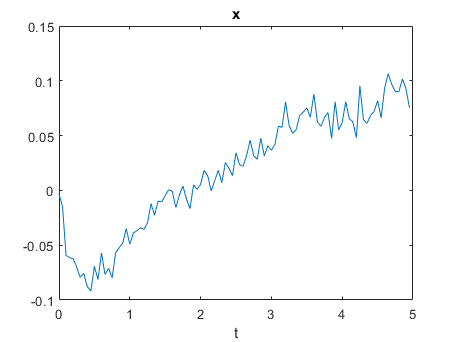

% Simulatie met python
arduino = tcpclient('127.0.0.1', 6012, 'Timeout', 60);

% Define parameters and modes
T_sample = 0.05;
n_samples = 100;
ts = (0:n_samples-1)*T_sample;

mode = CLASSICAL;
w = 0.0;
set_mode_params(arduino, mode, w, cat(1, 48.1, cat(1, zero(Rd2), pole(Rd2))));
reset_system(arduino);
Y = get_response(arduino, w, n_samples);

x = Y(1,:); theta = Y(2,:); u = Y(3,:);
figure; plot(ts, x); title("x"); xlabel('t')

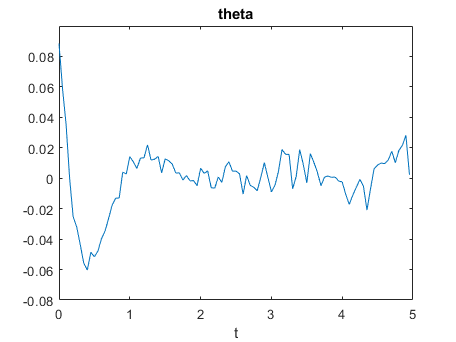

figure; plot(ts, theta); title("theta"); xlabel('t')

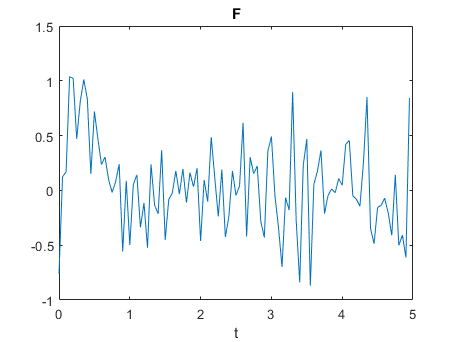

figure; plot(ts, u); title("F"); xlabel('t')

% Soms verschijnt er een initiële piek voor de kracht (F). Gezien dit
% slechts om een piek gaat vormt dit geen probleem. Het werkelijke systeem
% (met een limitatie op de kracht) zal zich misschien licht anders
% gedragen, maar de hoek zal toch gestabiliseerd worden.

close_connection(arduino)
clear arduino

Positie

% Enkel de transferfunctie van x (positie) beschouwen => SISO
Sdtf(1)

ans =
 
  From input "u" to output "x":
  0.002269 z^3 - 0.002416 z^2 - 0.002395 z + 0.002262
  ---------------------------------------------------
     z^4 - 4.069 z^3 + 6.129 z^2 - 4.051 z + 0.991
 
Sample time: 0.05 seconds
Discrete-time transfer function.



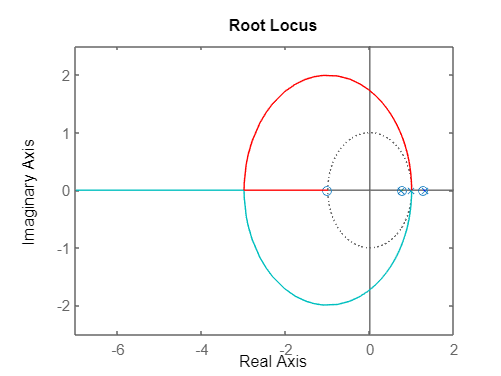


% Zonder regelaar
rlocus(Sd(1))

ps1 = pole(Sdtf(1)) % Het berekenen van de polen voor x

ps1 =     1.3210
    1.0000
    0.9929
    0.7555


% We merken op dat er reeds een pool op 1 ligt. Dit maakt dat voor de
% controle van de positie er automatisch zero-statische fout is VOOR HET SYSTEEM.
% MAAR: Nog niet voor de perturbaties een zero-static-error. Hiervoor zou
% er een pool in de regelaar moeten zijn.
zs1 = zero(Sdtf(1)) % Het berekenen van de nulpunten voor x

zs1 =    -0.9970
    1.2810
    0.7807


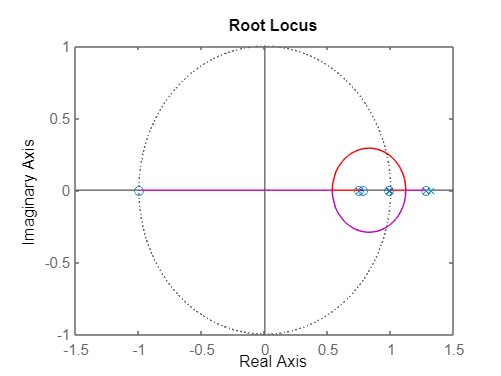

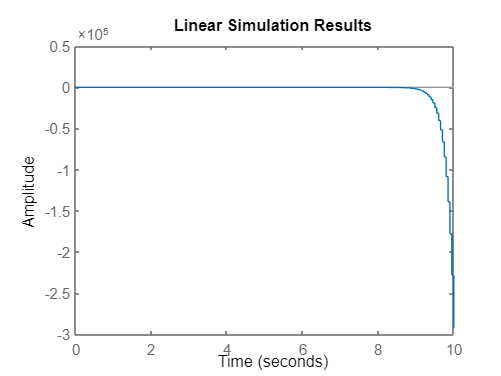

Error using DynamicSystem/lsim (line 97)
Cannot simulate the time response of improper (non-causal) models.


% Regelaar
Rd1 = zpk([ps1(3:4)],[zs1(2)],428,Ts); % Implementatie van een tweede PID
% Polen:
%   Om de pool rechts buiten de eenheidscirkel naar binnen te krijgen
%   plaatsen we een pool op het nulpunt rechts buiten de eenheidscirkel.
%   Deze zal vastgehouden worden door het nulpunt dat er ligt.% 
% Nulpunten:
%   Om de pool die van rechts komt en een imaginaire component krijgt
%   binnen de eenheidscirkel te trekken plaatsen we twee nulpunten in de
%   eenheidscirkel (1 was niet voldoende om de takken erin te krijgen). 
% Gain:
%   We wensen de polen binnen de eenheidscirkel te plaatsen en kiezen
%   ervoor om deze eveneens op de reële as te laten vallen teneinde geen
%   imaginair component te verkrijgen. Daardoor wordt het oscillair gedrag
%   vermeden. Om de waarde van de gain te bepalen werd de rootlocus geplot
%   en de gain bepaald op de positie waar de twee rechtse krommes elkaar
%   binnen de eenheidscirkel raken. We vinden dat een gain van 428
%   vereist is en steken deze onmiddelijk in de definitie van Rd1.
rlocus(Rd1*Sd(1))

% Probleem: Meer nulpunten dan polen in controller -> systeem F->y zal niet
% causaal zijn. Zie verder.

SdCl_pos_Loop = minreal(feedback(Rd1*Sdtf,[1 0]))

SdCl_pos_Loop =
 
  From input "u" to output...
       0.49268 (z+0.997) (z-0.7807)
   x:  ----------------------------
         (z^2 - 1.071z + 0.2867)
 
                1.238 (z+0.997) (z-1)^2
   theta:  ---------------------------------
           (z-1.281) (z^2 - 1.071z + 0.2867)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



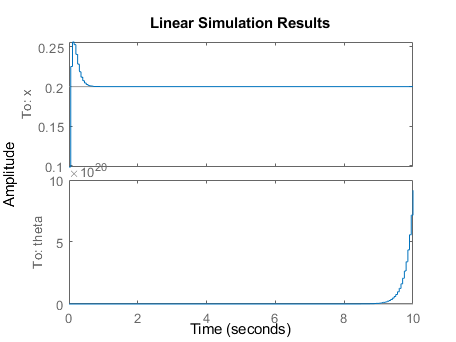

% Minreal vereenvoudigt de uitdrukking om het overzicht te bewaren.
% Enkel een feedback plaatsen op de hoek door [0 1]
lsim(minreal(feedback(Rd1*Sdtf,[1 0])),[0.2 0.2 0.2*ones(1,length(t)-2)],t)

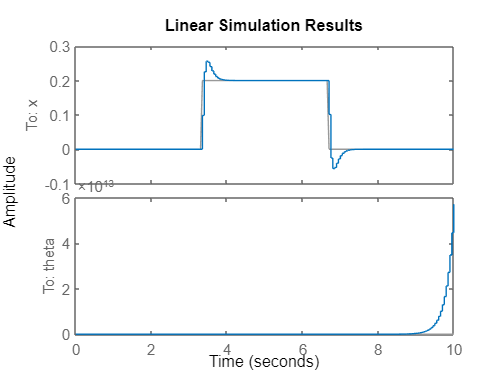

lsim(minreal(feedback(Rd1*Sdtf,[1 0])),[zeros(1,length(t)/3) 0.2*ones(1,length(t)/3) zeros(1,length(t)/3)],t)

% Het systeem volgt de opgelegde waarde.

t = 0:Ts:10;
% Er worden geen impulsen of stappen aangelegd aangezien de hoek in
% realiteit niet zo'n verloop heeft. Daarom wordt gebruikgemaakt van lsim.
lsim(feedback(Rd1*Sdtf(1),1),[0.3 0.3 zeros(1,length(t)-2)],t) % Output y

pole(feedback(Rd1*Sdtf(1),1))

ans =    0.7555 + 0.0000i
   0.5355 + 0.0020i
   0.5355 - 0.0020i
   0.9929 + 0.0000i
   1.2810 + 0.0000i


zero(feedback(Rd1*Sdtf(1),1))

ans =     0.7555
   -0.9970
    0.7807
    1.2810
    0.9929


% Zero op pool in 1.2810. Zou geen probleem mogen geven. Toch divergeert
% het systeem bij lsim

% lsim(feedback(Rd1,Sdtf(1)),[0.3 0.3 zeros(1,length(t)-2)],t) % Kracht F
pole(feedback(Rd1,Sdtf(1)))

ans =    1.2810 + 0.0000i
   0.9929 + 0.0000i
   0.5355 + 0.0020i
   0.5355 - 0.0020i
   0.7555 + 0.0000i


zero(feedback(Rd1,Sdtf(1)))

ans =     0.7555
    0.9929
    1.0000
    0.9929
    0.7555
    1.3210


% Voor deze lus ligt er een onbedekte pool in 1.2810 en zal het systeem dus
% divergeren. Bovendien is het systeem niet causaal omdat er meer nulpunten
% zijn dan polen.

% We concluderen dat de keuze voor een andere controller moet gemaakt
% worden. We hebben echter nog geen oplossing gevonden, dus zullen
% verdergaan met het ontwerpen van een observer voor x en de hoek.

## Observer